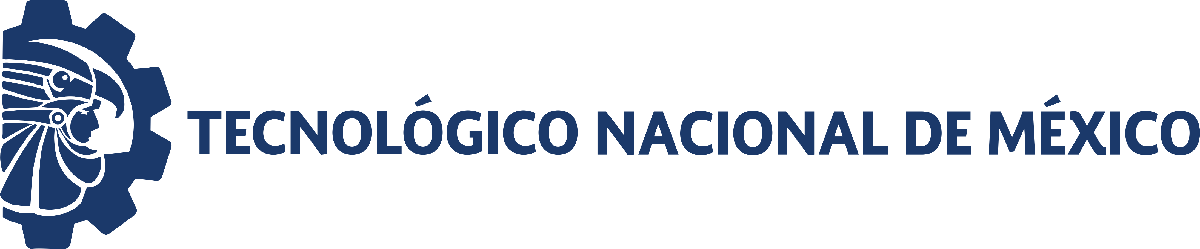                                 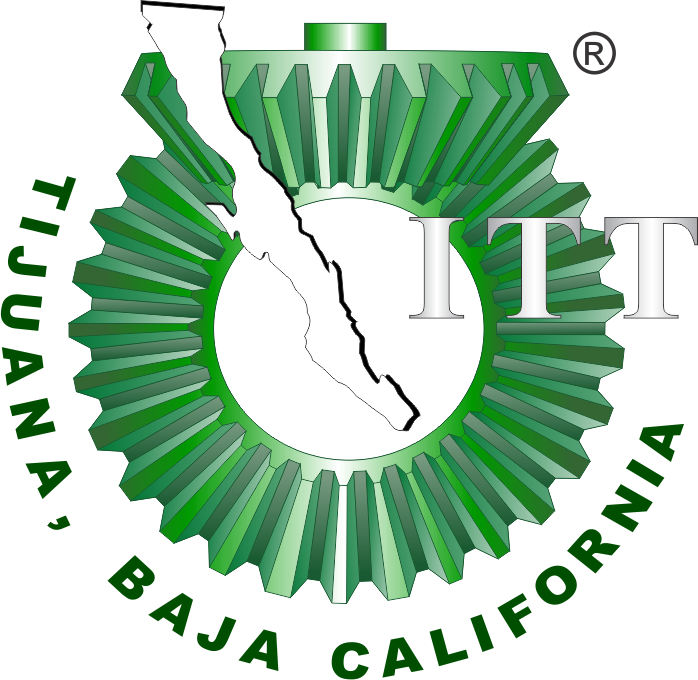

# Práctica: Regeneración de glóbulos rojos  

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

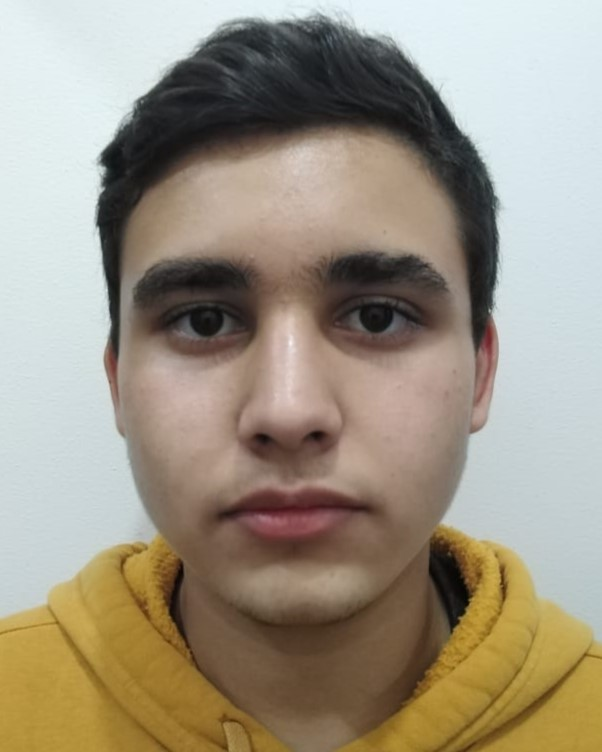

Nombre del alumno: **Rafael Herrera Aguilar**

Número de control: **22212258**

Correo institucional: **l22212258@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')

tend = 180; %tiempo de simulacion en dias 
dt = 1E-3; %Intervalo para el metodo de solucion por diferencias finitas 
n = round(tend/dt); %cantidad de iteraciones para el metodo numerico
%Condiciones iniciales base para cada paciente
x1_0 = 59; x2_0 = 44; x3_0 = 885;
%parametros particulares a cada paciente
gamma = [0.769, 0.388, 0.510, 0.590, 0.262, 0.324, 0.356, 0.089, 0.243, 0.057];
beta = [1.650, 0.867, 1.617, 2.615, 1.518, 2.676, 0.891, 2.557, 0.925, 0.089];
%intervalo para las condiciones inciales
xmin = 0.95; xmax = 1.05;
seed = 22212258; %Semilla para asegurar reproducibilidad
rng(seed, 'twister')
interval = xmin +(xmax - xmin).*rand(1,numel(gamma));
x1_0 = x1_0*interval; disp('x1_0 = '); disp(x1_0);...
x2_0 = x2_0*interval; disp('x2_0 = '); disp(x2_0);...
x3_0 = x3_0*interval; disp('x3_0 = '); disp(x3_0);

x1_0 = 
   58.2837   56.9020   56.3817   56.8495   57.1793   60.1951   58.3125   60.1429   57.8993   60.2531



x2_0 = 
   43.4658   42.4354   42.0474   42.3962   42.6422   44.8912   43.4873   44.8523   43.1791   44.9345



x3_0 = 
  874.2552  853.5304  845.7259  852.7427  857.6893  902.9258  874.6877  902.1438  868.4890  903.7969



## Caso: Sin transfusión sanguínea

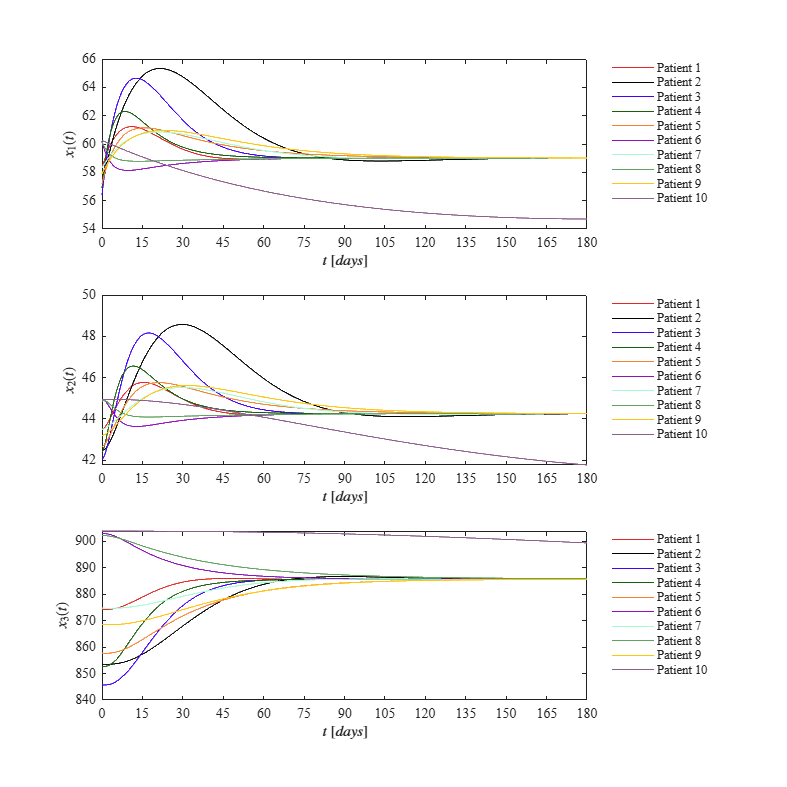

u = zeros(n+1,1);
fig = 1;
for i=1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end    

## Funciones

## Modelo matemático


$${\overset{\cdot }{x} }_1 =\beta \left(X_0 -k_1 x_1 \right)+\frac{\gamma \left(B_{\mathrm{ase}} -x_3 \right)\left(1-u\left(t\right)x_1 \right)}{B_{\mathrm{ase}} }$$



$${\overset{\ldotp }{x} }_2 =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$${\overset{\ldotp }{x} }_3 =\beta \left(k_2 x_2 -\alpha x_3 \right)-u\left(t\right)x_3$$


function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0,beta,gamma,u,dt,tend)
%parametreos fijos
Base = 885.42; X0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
t = (0:dt:tend)';
n = round(tend/dt);
x1 = zeros(n+1,1); x1(1)=x1_0;
x2 = zeros(n+1,1); x2(1)=x2_0;
x3 = zeros(n+1,1); x3(1)=x3_0;

    for i = 1:n
        x1(i+1) = x1(i) + (beta*(X0-k1*x1(i)) + gamma*(Base-x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*(k1*x1(i) - k2*x2(i)))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) - alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end

## Caso: Con transfusión de sangre 

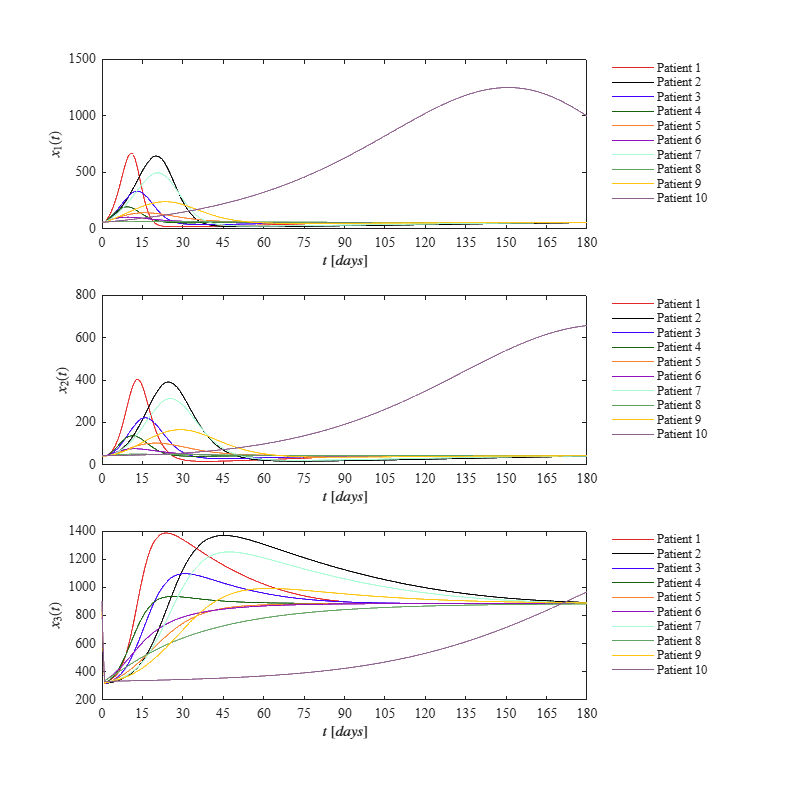

u = (t >= 0 & t <= 1);
fig = 2;
for i=1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end   

## Soluciones en el tiempo

function plotdata(t,x1,x2,x3,fig)
    set(figure(fig),'Color','w')
    set(gcf,'units','Centimeters','Position',[1,1,20,20])

    mycolors = [230, 039, 039;
                0, 0, 0;
                067, 0, 255;
                022, 097, 014;
                250, 129, 047;
                145, 018, 188;
                168, 251, 211;
                99, 163, 97;
                255, 197, 15;
                141, 95, 140]/255;

    subplot(3,1,1)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x1)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_1(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Times New Roman','FontSize',10)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

        subplot(3,1,2)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x2)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_2(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Times New Roman','FontSize',10)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

        subplot(3,1,3)
    hold on; grid off; box on; colororder(mycolors);
    plot(t,x3)
    xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
    ylabel('$x_3(t)$','Interpreter','latex','FontSize',10)
    xlim([0 180]); xticks(0:15:180)
    set(gca,'FontName','Times New Roman','FontSize',10)
    L = legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5',...
        'Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
    set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');

    if fig == 1
        exportgraphics(gcf,'Caso sin transfusion.pdf','ContentType','Vector')
    elseif fig == 2
        exportgraphics(gcf,'Caso con transfusion.pdf','ContentType','Vector')
    end
end